## Lecture 14:

#### Ex 1

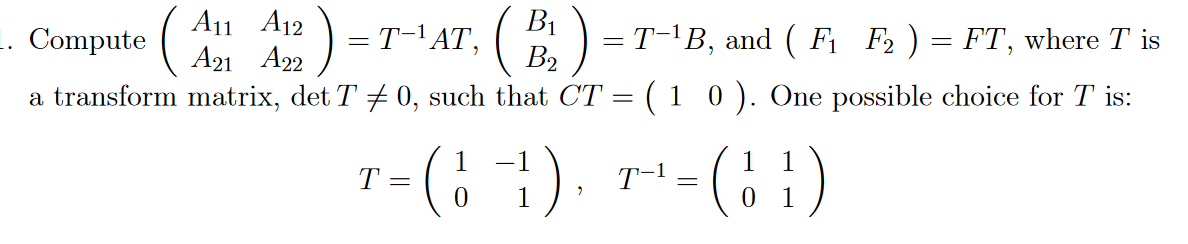

A = [7 -9; 6 -8];
B = [4;3];
C = [1 1];
F = [-2 2];
T = [1 -1; 0 1];
sys = ss(A,B,C,0);
TAT = inv(T)*A*T;
iTB = inv(T)*B;
FT = F*T;

syms l
L1 = solve(-14-30*l == -4);
L = -1/3;

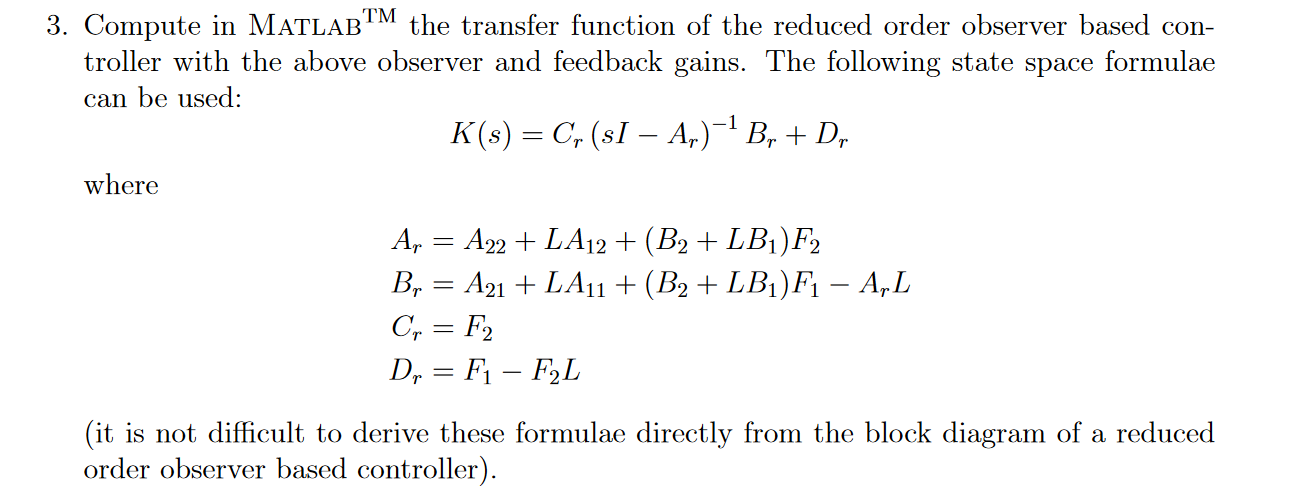

Ar = -14 + (L*-30)+(3 + (L*7))*4;
Br = 6 + (L*13)+(3 + (L*7))*(-2) - (Ar*L);
Cr =  4;
Dr = -2 - (4*L);
s = tf('s');
K = Cr*(s*eye(1) - Ar)^-1*Br+Dr %3

K =
 
  -0.6667 s - 1.333
  -----------------
      s + 1.333
 
Continuous-time transfer function.
Model Properties


syscl = feedback(sys,K,1);
pole(syscl)

ans =                         -4
                        -1
                        -2


x = feedback(K,1);

#### Ex 2:

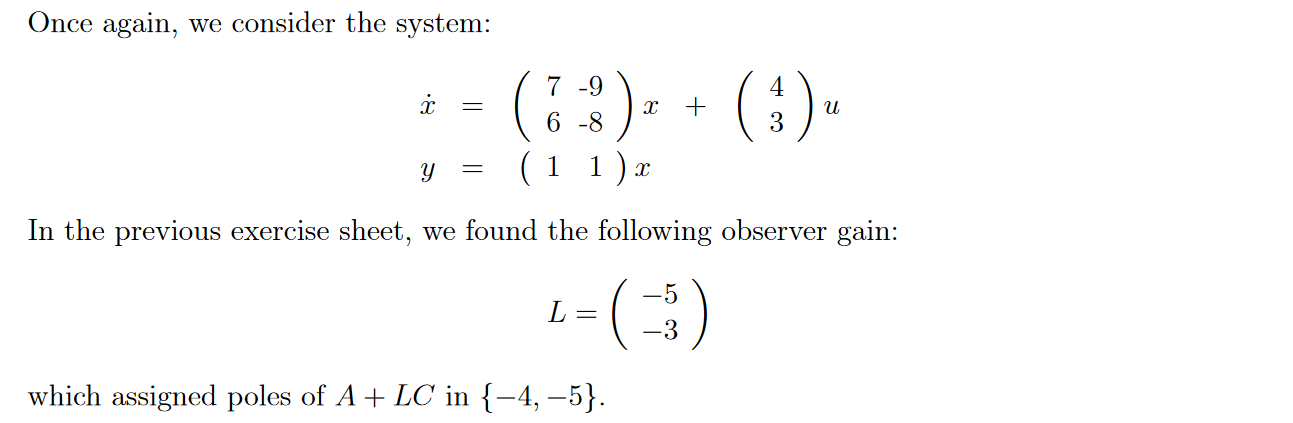

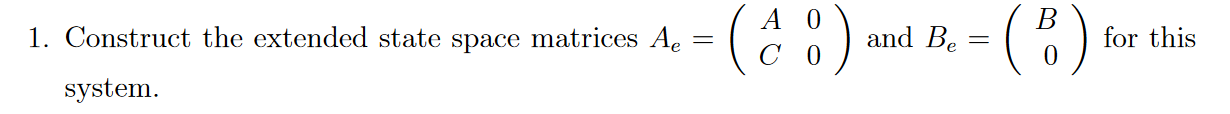

close all
clear
A = [7 -9; 6 -8];
B = [4;3];
C = [1 1];
T = [1 -1; 0 1];
%1
Ae = [7 -9 0; 6 -8 0; 1 1 0];
Be = [B;0];
Ce = [C 0];
L = [-5; -3];

Fe = -place(Ae,Be,-[1 2 3]);

F = [Fe(1) Fe(2)];
FI = Fe(3);

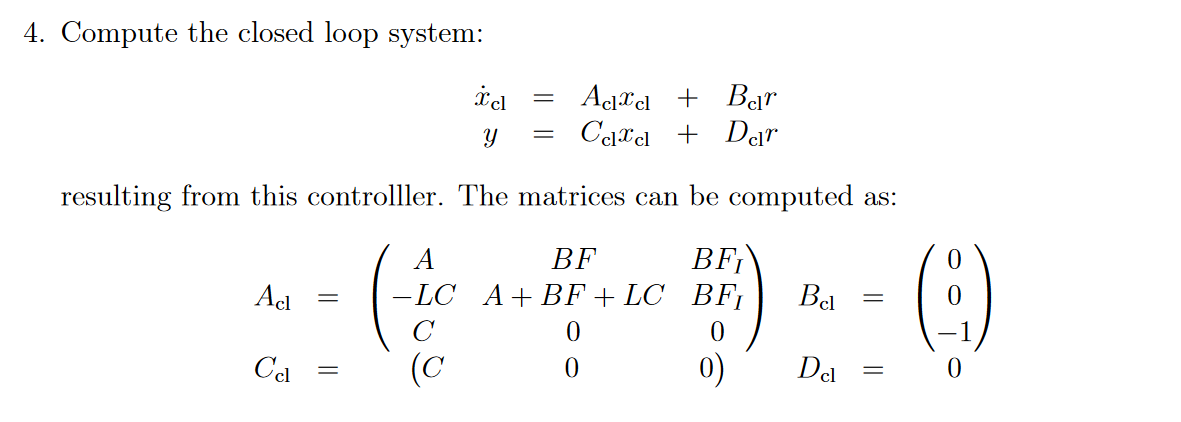

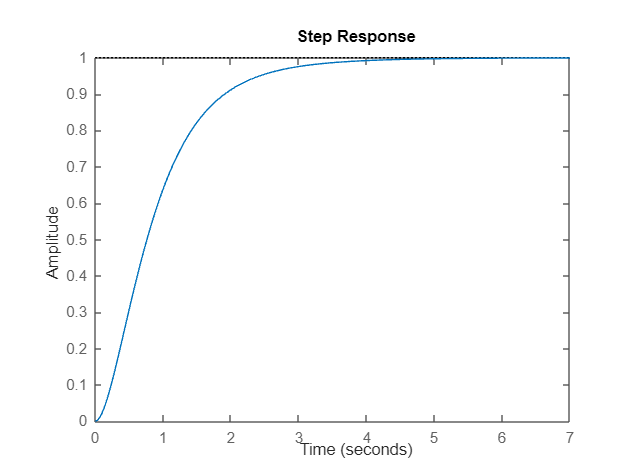

Acl = [A B*F B*FI;-L*C A+(B*F)+(L*C) B*FI; 1 1 0 0 0];
Bcl = [0;0;0;0;-1];
Ccl = [C 0 0 0];
Dcl = [0];
step(ss(Acl,Bcl,Ccl,Dcl)); 